clc; clear; close all;

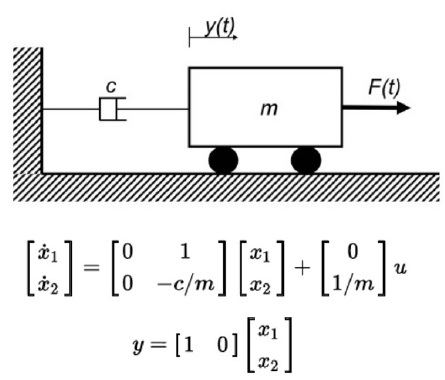

% Parametros del modelo.
m = 1;
c = 1;
A = [0 1; 0 -c/m];
B = [0 1/m]';
C = [1 0];
D = 0;

## Determine si el sistema es observable.

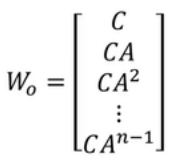

if (rank([C*eye(2); C*A]) == 2)
    disp('Es completamente observable desde la posición.')
else
    disp('No es completamente observable desde la posición.')
end

Es completamente observable desde la posición.


## Verifique si el sistema es observable para C=[0 1] . ¿Qué conclusión puede sacar?.

C = [0 1];
if (rank([C*eye(2); C*A]) == 2)
    disp('Es completamente observable desde la velocidad.')
else
    disp('No es completamente observable desde la velocidad.')
end

No es completamente observable desde la velocidad.


C = [1 0];

Intuitivamente, el carrito puede arrancar en distintas posiciones iniciales con velocidad nula, y sin excitación, se va a quedar ahí parado. Luego, midiendo la velocidad solamente (que va a ser nula), no vamos a ser capaces de determinar cuál es la posición del carrito. Es decir, que el estado inicial no lo podemos determinar midiendo solamente la velocidad.

## Ubique los polos del observador de modo que sean reales iguales.

Polos de la planta a lazo abierto.

% Para ver si difieren un poco, se propone que se tenga error en los
% parámetros del modelo
m_obs = m*1.2;
c_obs = c*1.2;
A_obs = [0 1; 0 -c_obs/m_obs];
B_obs = [0 1/m_obs]';
pLA   = eig(A_obs)

pLA =      0
    -1


El método Acker resulve el problema de determinar la matriz **K** para que $det(sI - A + BK)$tenga los polos en **p.** El problema que nosotros tenemos que resolver es el de determinar la matriz **L** para que $det(sI - A + LC)$tenga los polos en **p. **El determinante de una matriz es el de su matriz traspuesta, luego es lo mismo que obtener **L **para que $det(sI-A^T+C^{T}L^{T})$tenga los polos en **p**.

% acker(A, B, p)
p = min(pLA)*5*ones(2,1)

p =     -5
    -5


L = acker(A_obs.', C.', p); % En realidad se determina L^t
L = L.'

L =      9
    16


eig(A_obs-L*C) % Verificación

ans =     -5
    -5


## Sistema aumentado.

A_aug = [A zeros(2); L*C A_obs-L*C];
B_aug = [B;B_obs];
C_aug = eye(4);
D_aug = zeros(4, 1);
sys_aug = ss(A_aug, B_aug, C_aug, D_aug)

sys_aug =
 
  A = 
        x1   x2   x3   x4
   x1    0    1    0    0
   x2    0   -1    0    0
   x3    9    0   -9    1
   x4   16    0  -16   -1
 
  B = 
           u1
   x1       0
   x2       1
   x3       0
   x4  0.8333
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.



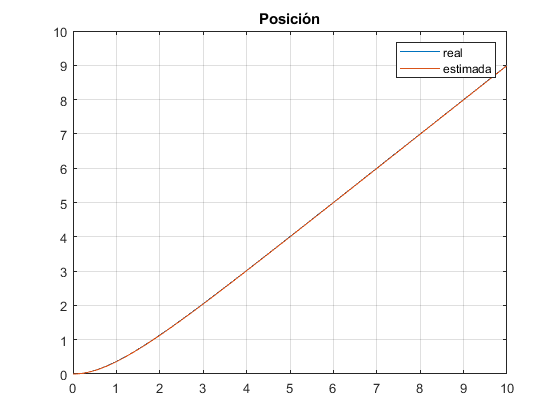

[Y, T, ~]= step(sys_aug, 10);
plot(T, Y(:, 1), T, Y(:, 3));
grid on;
legend('real', 'estimada')
title('Posición')

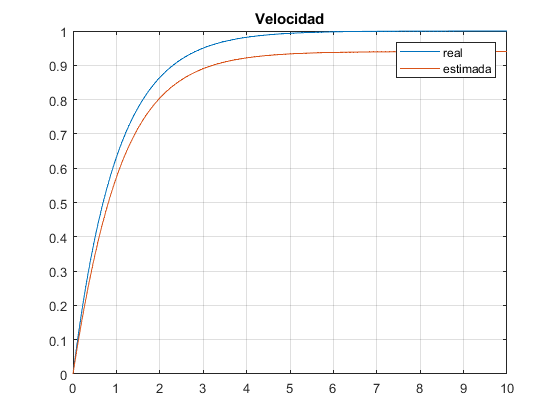

plot(T, Y(:, 2), T, Y(:, 4)); grid on;
legend('real', 'estimada')
title('Velocidad')

Cuando variamos los polos no pasa nada, porque justamente tenemos el mismo sistema replicado, osea, no pasa nada y no pasaría nada tampoco si no tuvieramos la realimentación del error de estimación, osea la matriz L.

Cuando se agrega error en la estimación de parámetros, lo que se obtiene es un error en estado permanente.